X = readraw_color("C:\Users\Ellis\Documents\HWFiles\digitalImgProcessing\project1\srcImages\girls.raw");

    "→Retrieving Image "    "C:\Users\Ellis\Documents\HWFiles\di…"    " ..."



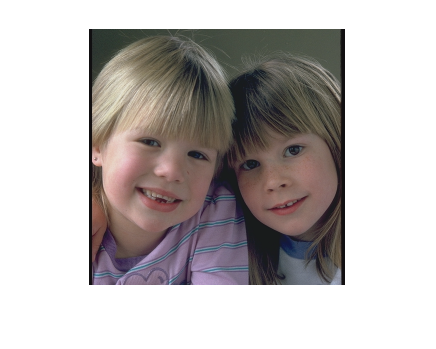

y = X(1,1,:);
imshow(X);

[L, W, c] = size(X);

px = X(1, 1, :);
disp(px);


(:,:,1) =

   17


(:,:,2) =

   15


(:,:,3) =

   17



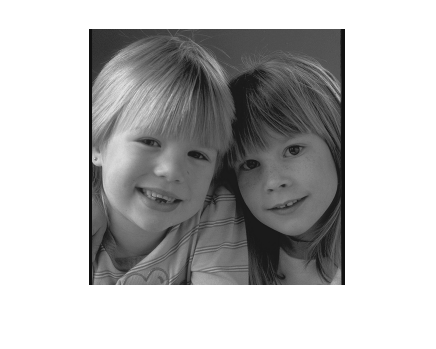

Gray = toGrayScale(X);
imshow(Gray);


toMark = readraw_color("..\srcImages\building_color.raw");

    "→Retrieving Image "    "..\srcImages\building_color.raw"    " ..."



mark = readraw_color("..\srcImages\cwru_logo_color.raw");

    "→Retrieving Image "    "..\srcImages\cwru_logo_color.raw"    " ..."



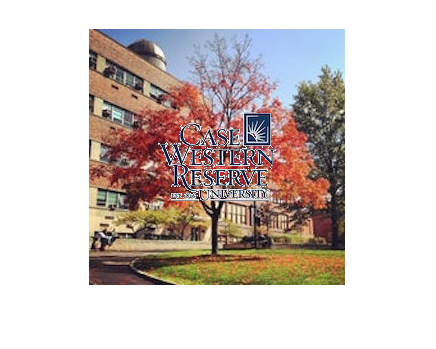


marked = waterMarkedCenterColor(toMark, mark);
imshow(marked);



mark = readraw("..\srcImages\cwru_logo_gray.raw");

    "→Retrieving Image "    "..\srcImages\cwru_logo_gray.raw"    " ..."



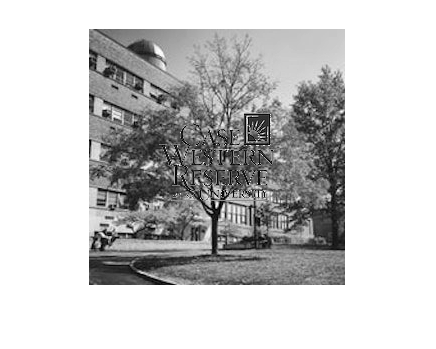

toMark = toGrayScale(toMark);

marked = waterMarkedCenterBW(toMark, mark);
imshow(marked);



jet = readraw_color("..\srcImages\F-16.raw");

    "→Retrieving Image "    "..\srcImages\F-16.raw"    " ..."



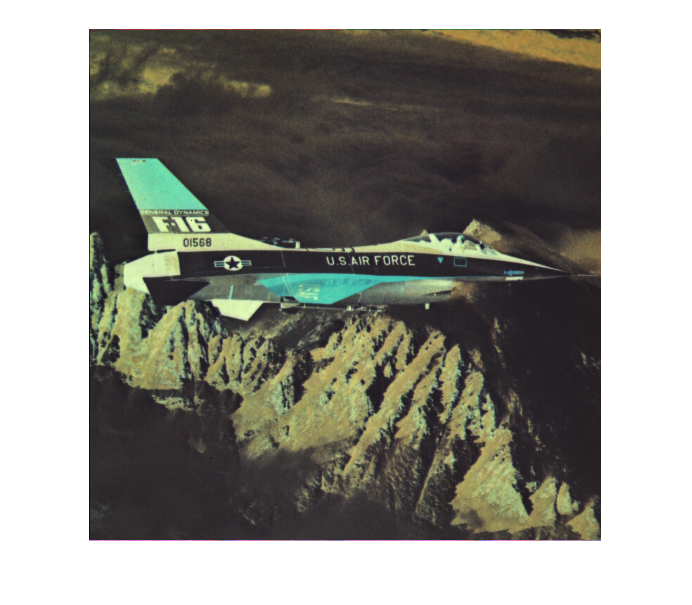

negJet = negativeImg(jet);
imshow(negJet);

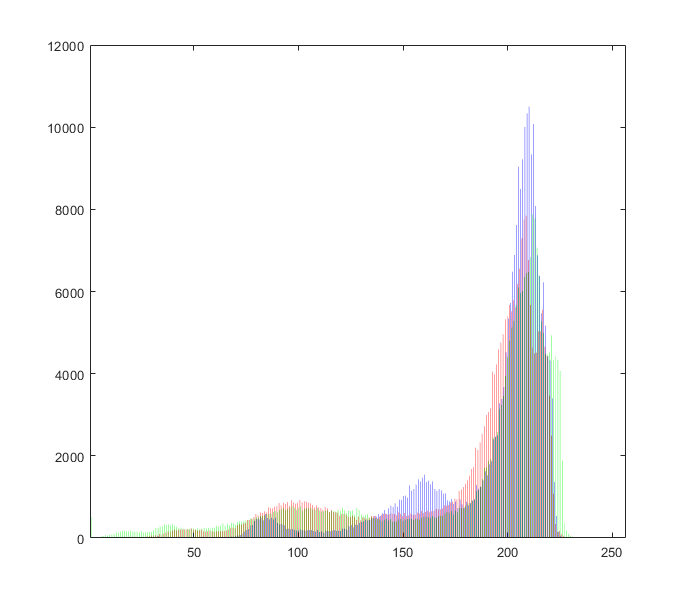


jetHist = histFor(jet, 3);
jetChart = bar(jetHist);
jetChart(1).FaceColor = 'r';
jetChart(2).FaceColor = 'g';
jetChart(3).FaceColor = 'b';

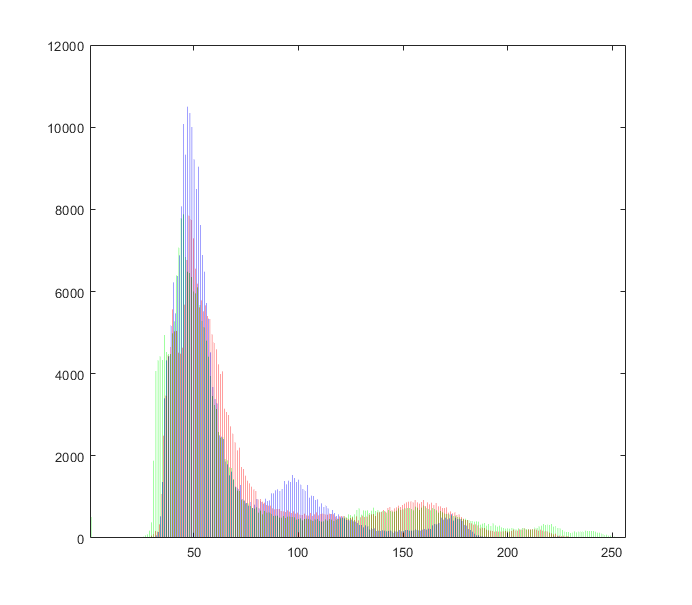


negHist = histFor(negJet, 3);
negChart = bar(negHist);
negChart(1).FaceColor = 'r';
negChart(2).FaceColor = 'g';
negChart(3).FaceColor = 'b';


%[w, h, ~] = size(mark);
%for x = 1:w
%    for y = 1:h
%        if ~isColorWhite(mark(x, y, :))
%            [r, g, b] = unpackColorPx(mark(x, y, :));
%            disp([r, g, b]);
%        end
%    end
%end

dark = readraw("..\srcImages\rose_dark.raw");

    "→Retrieving Image "    "..\srcImages\rose_dark.raw"    " ..."



mid = readraw("..\srcImages\rose_mid.raw");

    "→Retrieving Image "    "..\srcImages\rose_mid.raw"    " ..."



bright = readraw("..\srcImages\rose_bright.raw");

    "→Retrieving Image "    "..\srcImages\rose_bright.raw"    " ..."



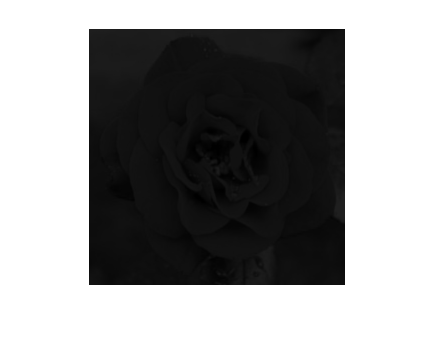


imshow(dark);

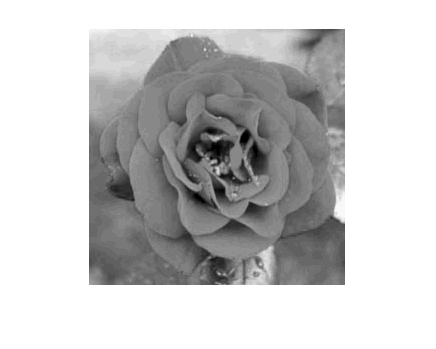

darkScaled = contrastLinearScaled(dark);
imshow(darkScaled);

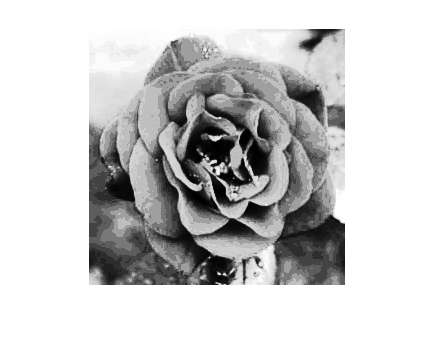

darkHistEq = contrastHistogramEqualized(dark);
imshow(darkHistEq);

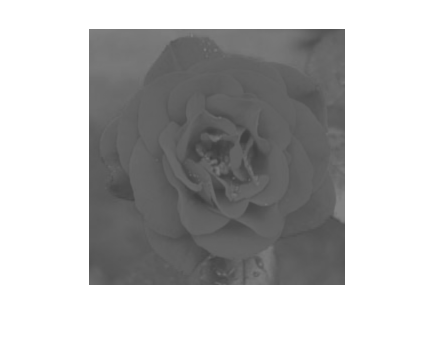


imshow(mid);

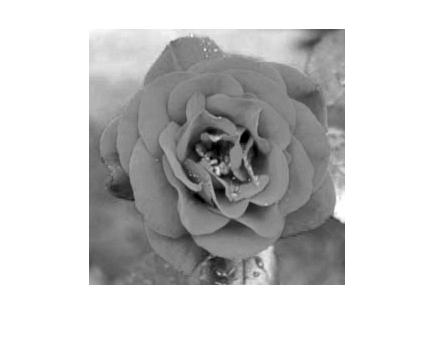

midScaled = contrastLinearScaled(mid);
imshow(midScaled);

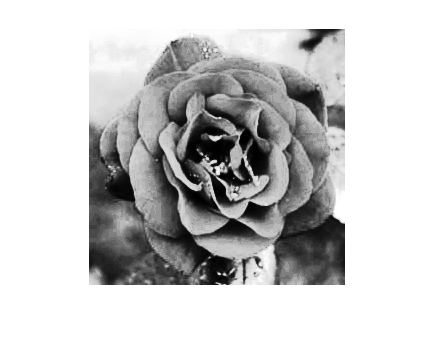

midHistEq = contrastHistogramEqualized(mid);
imshow(midHistEq);

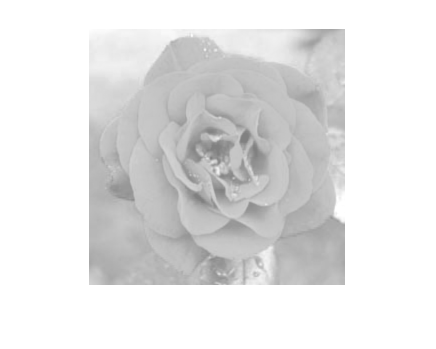


imshow(bright);

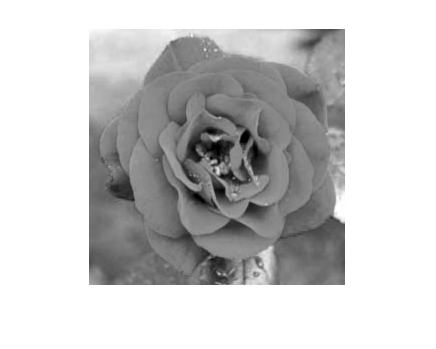

brightScaled = contrastLinearScaled(bright);
imshow(brightScaled);

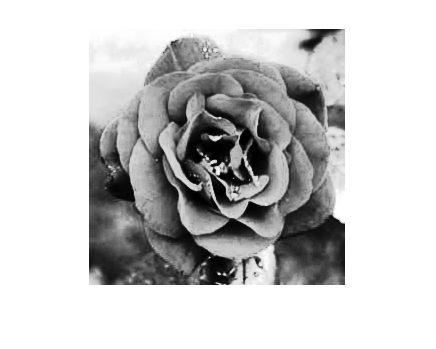

brightHistEq = contrastHistogramEqualized(bright);
imshow(brightHistEq);

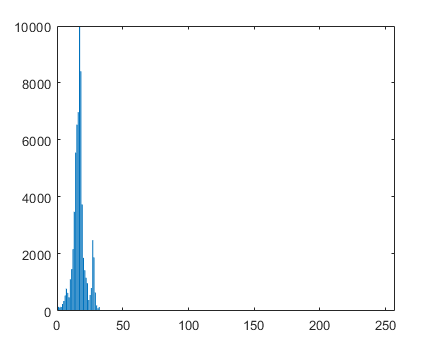


bar(histFor(dark, 1));

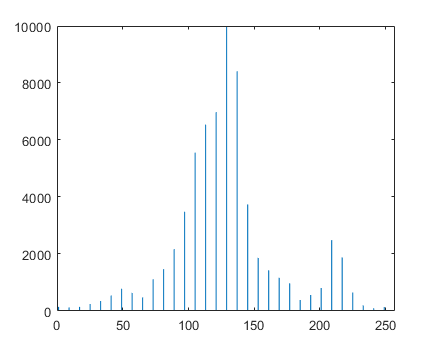

bar(histFor(darkScaled, 1));

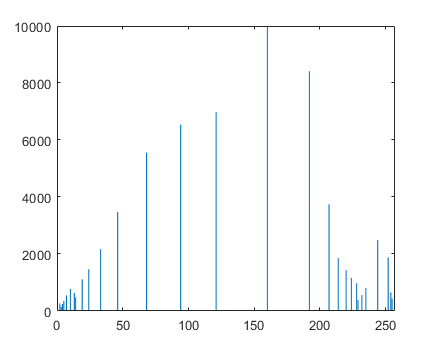

bar(histFor(darkHistEq, 1));

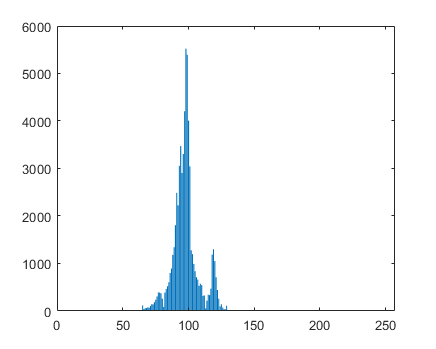

bar(histFor(mid, 1));

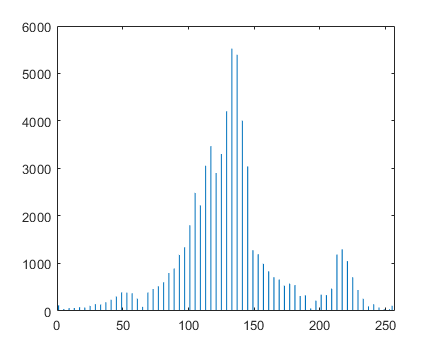

bar(histFor(midScaled, 1));

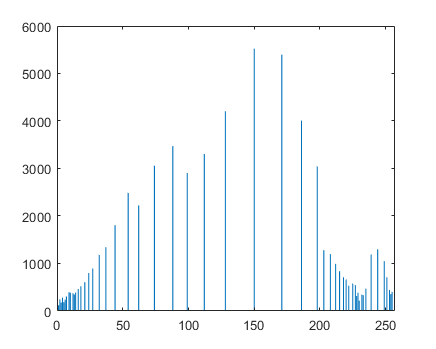

bar(histFor(midHistEq, 1));

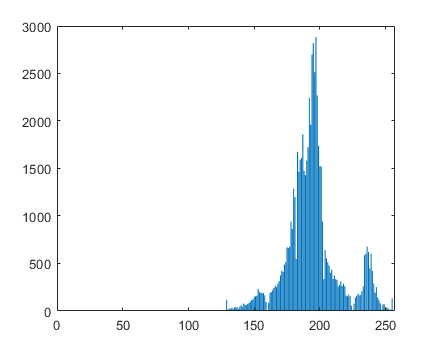

bar(histFor(bright, 1));

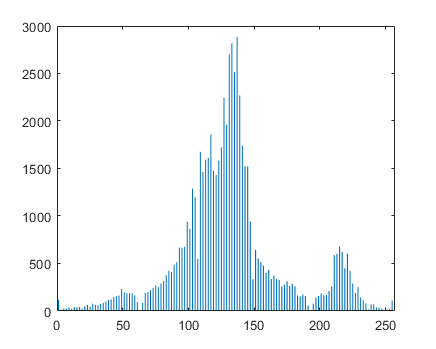

bar(histFor(brightScaled, 1));

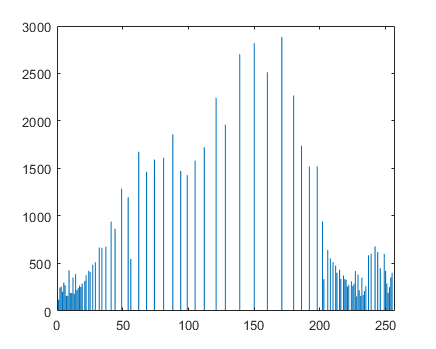

bar(histFor(brightHistEq, 1));

uniform = readraw("..\srcImages\rose_uni.raw");

    "→Retrieving Image "    "..\srcImages\rose_uni.raw"    " ..."



gauss = readraw("..\srcImages\rose_gau.raw");

    "→Retrieving Image "    "..\srcImages\rose_gau.raw"    " ..."



real = readraw("..\srcImages\rose.raw");

    "→Retrieving Image "    "..\srcImages\rose.raw"    " ..."



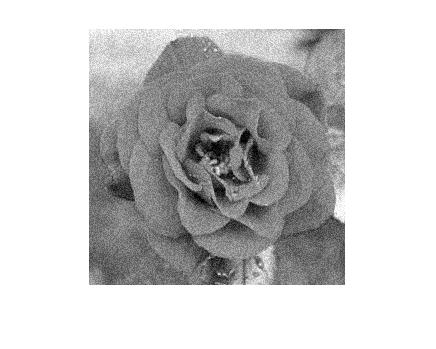


blurredUni = gaussBlur5x5(uniform);
imshow(uniform);

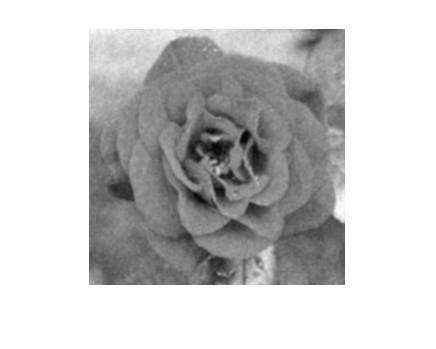

imshow(blurredUni);

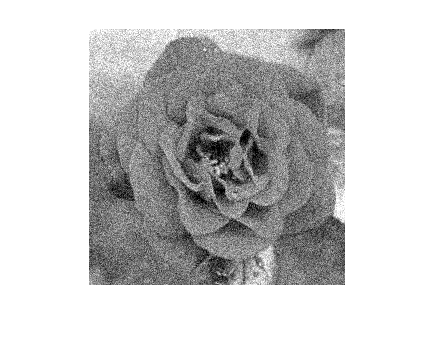


blurredGauss = applyMask(gauss, [1, 1, 1; 1, 1, 1; 1, 1, 1], 1/9);
blurredGauss2 = gaussBlur7x7(gauss);
sharp = applyMask(blurredGauss2, [0, -1, 0; -1, 5, -1; 0, -1, 0], 1);
imshow(gauss);

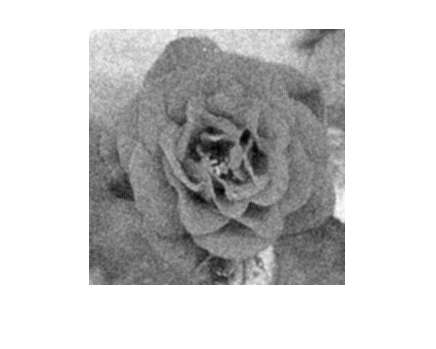

imshow(blurredGauss);

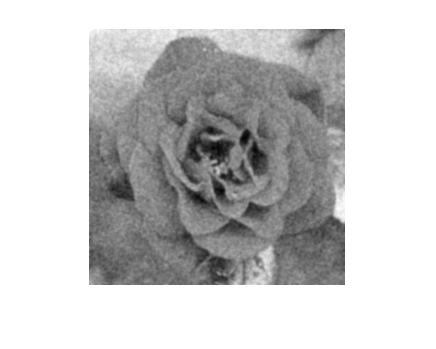

imshow(blurredGauss2);

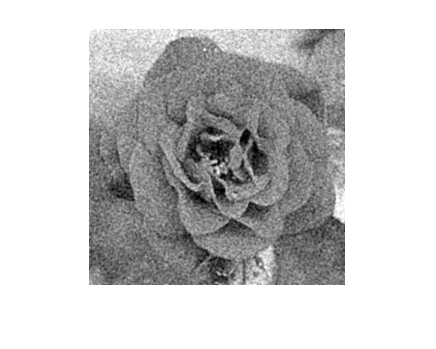

imshow(sharp);

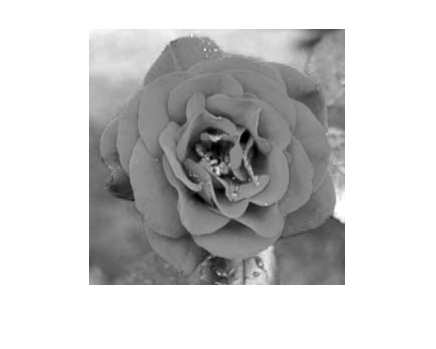

imshow(real);

colorNoise = readraw_color("..\srcImages\rose_color_noise.raw");

    "→Retrieving Image "    "..\srcImages\rose_color_noise.raw"    " ..."



colorReal = readraw_color("..\srcImages\rose_color.raw");

    "→Retrieving Image "    "..\srcImages\rose_color.raw"    " ..."



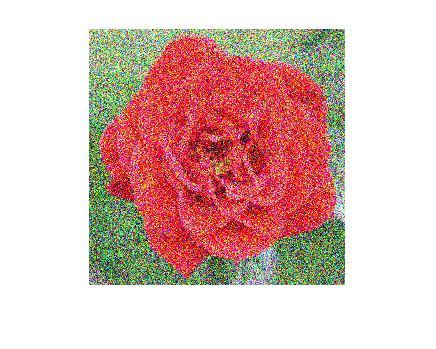


medianed = applyMedianFilter(colorNoise, 7);
medianed2 = applyMedianFilter(medianed, 7);
medianed3 = applyMedianFilter(medianed2, 5);
medianed4 = applyMedianFilter(medianed3, 5);
blurredMedian = gaussBlur5x5(medianed4);

%minimaximined = applyMaxminFilter(applyMinimaxFilter(colorNoise));
%blurrMinned = gaussBlur5x5(minimaximined);

%maximined = applyMinimaxFilter(applyMaxminFilter(colorNoise));
%blurrMaxed = gaussBlur5x5(maximined);


imshow(colorNoise);

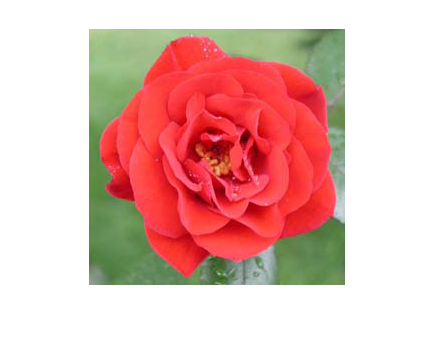

imshow(colorReal);

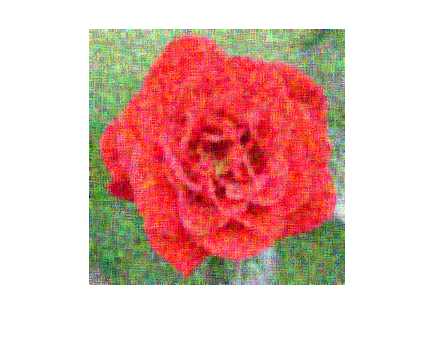

imshow(medianed);

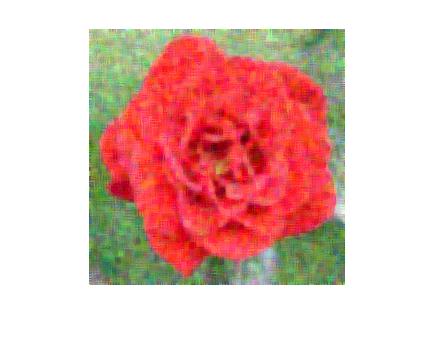

imshow(medianed2);

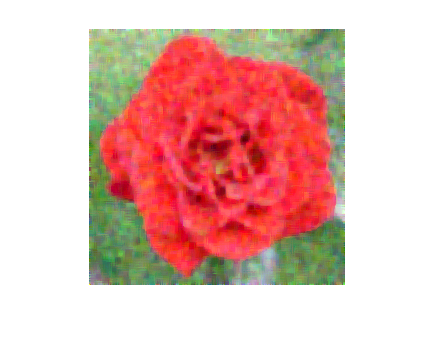

imshow(medianed3);

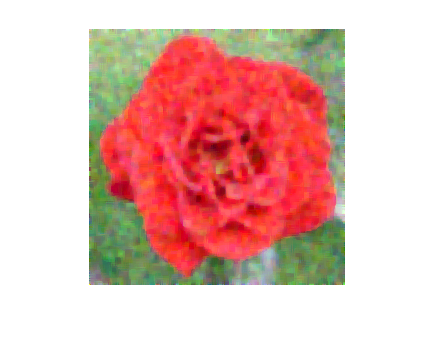

imshow(medianed4);

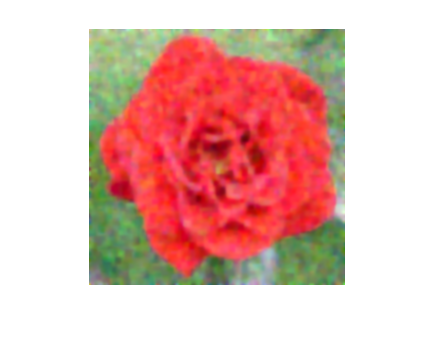

imshow(blurredMedian);

%imshow(blurrMinned);
%imshow(blurrMaxed);
